## **Trim Input Variation Plot**

Helicopter Emergency Rescue (HER25)

***HER05**** Flight Mechanics, Performance & Control - Hanchen Li*

% Housekeeping
clear
clc
close all

### 0 Input

Manually input data from optimiser

**0.1 Data Point**

% Trim Point
v_F_t = 66.877777778; % 130 knots = 66.877777778 m/s

% Vertical Climb
% from 0 to 10 m/s
v_C = [0, 3, 6, 9, 12];

% Forward Flight
% from 0 to 80 m/s
v_F = [0, 25, 50, v_F_t, 82];

**0.2 MTOW**

% Hover
theta_LR_H_1 = 0;
theta_UR_H_1 = 0;
theta_1s_H_1 = 0;
theta_1c_H_1 = 0;
phi_H_1      = 0;
theta_H_1    = 0;
delta_E_H_1  = 0;
delta_R_H_1  = 0;

% Trim Point
theta_LR_t_1 = 0.5;
theta_UR_t_1 = 0.5;
theta_1s_t_1 = 0.5;
theta_1c_t_1 = 0.5;
phi_t_1      = 0.5;
theta_t_1    = 0.5;
delta_E_t_1  = 0.5;
delta_R_t_1  = 0.5;

% Vertical Climb
theta_LR_C_1 = [theta_LR_H_1, 0.3, 0.1, 0.2, 0.4];
theta_UR_C_1 = [theta_UR_H_1, 0.1, 0.2, 0.3, 0.4];
theta_1s_C_1 = [theta_1s_H_1, 0.1, 0.2, 0.3, 0.4];
theta_1c_C_1 = [theta_1c_H_1, 0.1, 0.2, 0.3, 0.4];
phi_C_1      = [phi_H_1, 0.1, 0.2, 0.3, 0.4];
theta_C_1    = [theta_H_1, 0.1, 0.2, 0.3, 0.4];

% Forward Flight
theta_LR_F_1 = [theta_LR_H_1, 0.3, 0.2, theta_LR_t_1, 0.6];
theta_UR_F_1 = [theta_UR_H_1, 0.1, 0.2, theta_UR_t_1, 0.5];
theta_1s_F_1 = [theta_1s_H_1, 0.1, 0.2, theta_1s_t_1, 0.5];
theta_1c_F_1 = [theta_1c_H_1, 0.1, 0.2, theta_1c_t_1, 0.5];
phi_F_1      = [phi_H_1, 0.1, 0.2, phi_t_1, 0.5];
theta_F_1    = [theta_H_1, 0.1, 0.2, theta_t_1, 0.5];
delta_E_F_1  = [delta_E_H_1, 0.1, 0.2, delta_E_t_1, 0.5];
delta_R_F_1  = [delta_R_H_1, 0.1, 0.2, delta_R_t_1, 0.5];

**0.3 MZFW**

% Hover
theta_LR_H_2 = 0;
theta_UR_H_2 = 0;
theta_1s_H_2 = 0;
theta_1c_H_2 = 0;
phi_H_2      = 0;
theta_H_2    = 0;
delta_E_H_2  = 0;
delta_R_H_2  = 0;

% Trim Point
v_F_t_2 = 66.877777778; % 130 knots = 66.877777778 m/s
theta_LR_t_2 = 0.6;
theta_UR_t_2 = 0.6;
theta_1s_t_2 = 0.6;
theta_1c_t_2 = 0.6;
phi_t_2      = 0.6;
theta_t_2    = 0.6;
delta_E_t_2  = 0.6;
delta_R_t_2  = 0.6;

% Vertical Climb
theta_LR_C_2 = [theta_LR_H_2, 0.2, 0.3, 0.4, 0.5];
theta_UR_C_2 = [theta_UR_H_2, 0.2, 0.3, 0.4, 0.5];
theta_1s_C_2 = [theta_1s_H_2, 0.2, 0.3, 0.4, 0.5];
theta_1c_C_2 = [theta_1c_H_2, 0.2, 0.3, 0.4, 0.5];
phi_C_2      = [phi_H_2, 0.2, 0.3, 0.4, 0.5];
theta_C_2    = [theta_H_2, 0.2, 0.3, 0.4, 0.5];

% Forward Flight
theta_LR_F_2 = [theta_LR_H_2, 0.2, 0.3, theta_LR_t_2, 0.7];
theta_UR_F_2 = [theta_UR_H_2, 0.2, 0.3, theta_UR_t_2, 0.7];
theta_1s_F_2 = [theta_1s_H_2, 0.2, 0.3, theta_1s_t_2, 0.7];
theta_1c_F_2 = [theta_1c_H_2, 0.2, 0.3, theta_1c_t_2, 0.7];
phi_F_2      = [phi_H_2, 0.2, 0.3, phi_t_2, 0.7];
theta_F_2    = [theta_H_2, 0.2, 0.3, theta_t_2, 0.7];
delta_E_F_2  = [delta_E_H_2, 0.2, 0.3, delta_E_t_2, 0.7];
delta_R_F_2  = [delta_R_H_2, 0.2, 0.3, delta_R_t_2, 0.7];

**0.4 Maximum Fuel with Zero Payload**

% Hover
theta_LR_H_3 = 0;
theta_UR_H_3 = 0;
theta_1s_H_3 = 0;
theta_1c_H_3 = 0;
phi_H_3      = 0;
theta_H_3    = 0;
delta_E_H_3  = 0;
delta_R_H_3  = 0;

% Trim Point
theta_LR_t_3 = 0.7;
theta_UR_t_3 = 0.7;
theta_1s_t_3 = 0.7;
theta_1c_t_3 = 0.7;
phi_t_3      = 0.7;
theta_t_3    = 0.7;
delta_E_t_3  = 0.6;
delta_R_t_3  = 0.6;

% Vertical Climb
theta_LR_C_3 = [theta_LR_H_3, 0.3, 0.4, 0.5, 0.6];
theta_UR_C_3 = [theta_UR_H_3, 0.3, 0.4, 0.5, 0.6];
theta_1s_C_3 = [theta_1s_H_3, 0.3, 0.4, 0.5, 0.6];
theta_1c_C_3 = [theta_1c_H_3, 0.3, 0.4, 0.5, 0.6];
phi_C_3      = [phi_H_3, 0.3, 0.4, 0.5, 0.6];
theta_C_3    = [theta_H_3, 0.3, 0.4, 0.5, 0.6];

% Forward Flight
theta_LR_F_3 = [theta_LR_H_3, 0.3, 0.4, theta_LR_t_3, 0.7];
theta_UR_F_3 = [theta_UR_H_3, 0.3, 0.4, theta_UR_t_3, 0.7];
theta_1s_F_3 = [theta_1s_H_3, 0.3, 0.4, theta_1s_t_3, 0.7];
theta_1c_F_3 = [theta_1c_H_3, 0.3, 0.4, theta_1c_t_3, 0.7];
phi_F_3      = [phi_H_3, 0.3, 0.4, phi_t_3, 0.7];
theta_F_3    = [theta_H_3, 0.3, 0.4, theta_t_3, 0.7];
delta_E_F_3  = [delta_E_H_3, 0.3, 0.4, delta_E_t_3, 0.7];
delta_R_F_3  = [delta_R_H_3, 0.3, 0.4, delta_R_t_3, 0.7];

**0.5 Linearization Point**

TBD (most likely the segment when crusing with patient cause its most important)

% Hover
theta_LR_H_4 = 0;
theta_UR_H_4 = 0;
theta_1s_H_4 = 0;
theta_1c_H_4 = 0;
phi_H_4      = 0;
theta_H_4    = 0;
delta_E_H_4  = 0;
delta_R_H_4  = 0;

% Trim Point
theta_LR_t_4 = 0.7;
theta_UR_t_4 = 0.7;
theta_1s_t_4 = 0.7;
theta_1c_t_4 = 0.7;
phi_t_4      = 0.7;
theta_t_4    = 0.7;
delta_E_t_4  = 0.6;
delta_R_t_4  = 0.6;

% Vertical Climb
theta_LR_C_4 = [theta_LR_H_4, 0.4, 0.5, 0.6, 0.7];
theta_UR_C_4 = [theta_UR_H_4, 0.4, 0.5, 0.6, 0.7];
theta_1s_C_4 = [theta_1s_H_4, 0.4, 0.5, 0.6, 0.7];
theta_1c_C_4 = [theta_1c_H_4, 0.4, 0.5, 0.6, 0.7];
phi_C_4      = [phi_H_4, 0.4, 0.5, 0.6, 0.7];
theta_C_4    = [theta_H_4, 0.4, 0.5, 0.6, 0.7];

% Forward Flight
theta_LR_F_4 = [theta_LR_H_4, 0.4, 0.5, theta_LR_t_4, 0.8];
theta_UR_F_4 = [theta_UR_H_4, 0.4, 0.5, theta_UR_t_4, 0.8];
theta_1s_F_4 = [theta_1s_H_4, 0.4, 0.5, theta_1s_t_4, 0.8];
theta_1c_F_4 = [theta_1c_H_4, 0.4, 0.5, theta_1c_t_4, 0.8];
phi_F_4      = [phi_H_4, 0.4, 0.5, phi_t_4, 0.8];
theta_F_4    = [theta_H_4, 0.4, 0.5, theta_t_4, 0.8];
delta_E_F_4  = [delta_E_H_4, 0.4, 0.5, delta_E_t_4, 0.8];
delta_R_F_4  = [delta_R_H_4, 0.4, 0.5, delta_R_t_4, 0.8];

### 2 Plotting

**2.1 Hover and vertical climb**

v_C_fine = linspace(min(v_C), max(v_C), 200);

theta_LR

% MTOW
theta_LR_C_1_interp = interp1(v_C, theta_LR_C_1, v_C_fine, 'pchip');

% MZFW
theta_LR_C_2_interp = interp1(v_C, theta_LR_C_2, v_C_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_LR_C_3_interp = interp1(v_C, theta_LR_C_3, v_C_fine, 'pchip');

% Linearization Point
theta_LR_C_4_interp = interp1(v_C, theta_LR_C_4, v_C_fine, 'pchip');

theta_UR

% MTOW
theta_UR_C_1_interp = interp1(v_C, theta_UR_C_1, v_C_fine, 'pchip');

% MZFW
theta_UR_C_2_interp = interp1(v_C, theta_UR_C_2, v_C_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_UR_C_3_interp = interp1(v_C, theta_UR_C_3, v_C_fine, 'pchip');

% Linearization Point
theta_UR_C_4_interp = interp1(v_C, theta_UR_C_4, v_C_fine, 'pchip');

theta_ls

% MTOW
theta_1s_C_1_interp = interp1(v_C, theta_1s_C_1, v_C_fine, 'pchip');

% MZFW
theta_1s_C_2_interp = interp1(v_C, theta_1s_C_2, v_C_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_1s_C_3_interp = interp1(v_C, theta_1s_C_3, v_C_fine, 'pchip');

% Linearization Point
theta_1s_C_4_interp = interp1(v_C, theta_1s_C_4, v_C_fine, 'pchip');

theta_lc

% MTOW
theta_1c_C_1_interp = interp1(v_C, theta_1c_C_1, v_C_fine, 'pchip');

% MZFW
theta_1c_C_2_interp = interp1(v_C, theta_1c_C_2, v_C_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_1c_C_3_interp = interp1(v_C, theta_1c_C_3, v_C_fine, 'pchip');

% Linearization Point
theta_1c_C_4_interp = interp1(v_C, theta_1c_C_4, v_C_fine, 'pchip');

phi

% MTOW
phi_C_1_interp = interp1(v_C, phi_C_1, v_C_fine, 'pchip');

% MZFW
phi_C_2_interp = interp1(v_C, phi_C_2, v_C_fine, 'pchip');

% Maximum Fuel with Zero Payload
phi_C_3_interp = interp1(v_C, phi_C_3, v_C_fine, 'pchip');

% Linearization Point
phi_C_4_interp = interp1(v_C, phi_C_4, v_C_fine, 'pchip');

theta

% MTOW
theta_C_1_interp = interp1(v_C, theta_C_1, v_C_fine, 'pchip');

% MZFW
theta_C_2_interp = interp1(v_C, theta_C_2, v_C_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_C_3_interp = interp1(v_C, theta_C_3, v_C_fine, 'pchip');

% Linearization Point
theta_C_4_interp = interp1(v_C, theta_C_4, v_C_fine, 'pchip');

**2.2 Hover and forward Flight**

v_F_fine = linspace(min(v_F), max(v_F), 200);

theta_LR

% MTOW
theta_LR_F_1_interp = interp1(v_F, theta_LR_F_1, v_F_fine, 'pchip');

% MZFW
theta_LR_F_2_interp = interp1(v_F, theta_LR_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_LR_F_3_interp = interp1(v_F, theta_LR_F_3, v_F_fine, 'pchip');

% Linearization Point
theta_LR_F_4_interp = interp1(v_F, theta_LR_F_4, v_F_fine, 'pchip');

theta_UR

% MTOW
theta_UR_F_1_interp = interp1(v_F, theta_UR_F_1, v_F_fine, 'pchip');

% MZFW
theta_UR_F_2_interp = interp1(v_F, theta_UR_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_UR_F_3_interp = interp1(v_F, theta_UR_F_3, v_F_fine, 'pchip');

% Linearization Point
theta_UR_F_4_interp = interp1(v_F, theta_UR_F_4, v_F_fine, 'pchip');

theta_ls

% MTOW
theta_1s_F_1_interp = interp1(v_F, theta_1s_F_1, v_F_fine, 'pchip');

% MZFW
theta_1s_F_2_interp = interp1(v_F, theta_1s_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_1s_F_3_interp = interp1(v_F, theta_1s_F_3, v_F_fine, 'pchip');

% Linearization Point
theta_1s_F_4_interp = interp1(v_F, theta_1s_F_4, v_F_fine, 'pchip');

theta_lc

% MTOW
theta_1c_F_1_interp = interp1(v_F, theta_1c_F_1, v_F_fine, 'pchip');

% MZFW
theta_1c_F_2_interp = interp1(v_F, theta_1c_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_1c_F_3_interp = interp1(v_F, theta_1c_F_3, v_F_fine, 'pchip');

% Linearization Point
theta_1c_F_4_interp = interp1(v_F, theta_1c_F_4, v_F_fine, 'pchip');

phi

% MTOW
phi_F_1_interp = interp1(v_F, phi_F_1, v_F_fine, 'pchip');

% MZFW
phi_F_2_interp = interp1(v_F, phi_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
phi_F_3_interp = interp1(v_F, phi_F_3, v_F_fine, 'pchip');

% Linearization Point
phi_F_4_interp = interp1(v_F, phi_F_4, v_F_fine, 'pchip');

theta

% MTOW
theta_F_1_interp = interp1(v_F, theta_F_1, v_F_fine, 'pchip');

% MZFW
theta_F_2_interp = interp1(v_F, theta_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
theta_F_3_interp = interp1(v_F, theta_F_3, v_F_fine, 'pchip');

% Linearization Point
theta_F_4_interp = interp1(v_F, theta_F_4, v_F_fine, 'pchip');

delta_E

% MTOW
delta_E_F_1_interp = interp1(v_F, delta_E_F_1, v_F_fine, 'pchip');

% MZFW
delta_E_F_2_interp = interp1(v_F, delta_E_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
delta_E_F_3_interp = interp1(v_F, delta_E_F_3, v_F_fine, 'pchip');

% Linearization Point
delta_E_F_4_interp = interp1(v_F, delta_E_F_4, v_F_fine, 'pchip');

delta_R

% MTOW
delta_R_F_1_interp = interp1(v_F, delta_R_F_1, v_F_fine, 'pchip');

% MZFW
delta_R_F_2_interp = interp1(v_F, delta_R_F_2, v_F_fine, 'pchip');

% Maximum Fuel with Zero Payload
delta_R_F_3_interp = interp1(v_F, delta_R_F_3, v_F_fine, 'pchip');

% Linearization Point
delta_R_F_4_interp = interp1(v_F, delta_R_F_4, v_F_fine, 'pchip');

### 2 Plotting

**2.1 Hover and vertical climb**

theta_LR

figure(1)

clf;

subplot(6,1,1)

% MTOW
plot(v_C_fine, theta_LR_C_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5)
hold on

% MZFW
plot(v_C_fine, theta_LR_C_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C_fine, theta_LR_C_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5)
hold on

% Linearization Point
plot(v_C_fine, theta_LR_C_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5)
hold on

% MTOW
plot(v_C, theta_LR_C_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% MZFW
plot(v_C, theta_LR_C_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C, theta_LR_C_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_C, theta_LR_C_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Vertical lines
plot(0, [0 max(theta_LR_C_1 .* 180 ./ pi) + 5], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5, 'LineWidth', 5)
hold off

% Legends
legend("MTOW", "MZFW", "Maximum Fuel with Zero Payload", "Linearization Point", "Location",  "best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
ylabel('$\theta_{LR} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([min(v_C) max(v_C)]);
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'on'; 

theta_UR

subplot(6,1,2)

% MTOW
plot(v_C_fine, theta_LR_C_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5)
hold on

% MZFW
plot(v_C_fine, theta_LR_C_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C_fine, theta_LR_C_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5)
hold on

% Linearization Point
plot(v_C_fine, theta_LR_C_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5)
hold on

% MTOW
plot(v_C, theta_LR_C_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% MZFW
plot(v_C, theta_LR_C_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C, theta_LR_C_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_C, theta_LR_C_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Vertical lines
plot(0, [0 max(theta_LR_C_1 .* 180 ./ pi) + 5], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5, 'LineWidth', 5)
hold off

% Axis labels with LaTeX font
ylabel('$\theta_{LR} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([min(v_C) max(v_C)]);
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'on'; 

theta_ls

subplot(6,1,3)

% MTOW
plot(v_C_fine, theta_LR_C_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5)
hold on

% MZFW
plot(v_C_fine, theta_LR_C_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C_fine, theta_LR_C_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5)
hold on

% Linearization Point
plot(v_C_fine, theta_LR_C_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5)
hold on

% MTOW
plot(v_C, theta_LR_C_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% MZFW
plot(v_C, theta_LR_C_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C, theta_LR_C_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_C, theta_LR_C_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Vertical lines
plot(0, [0 max(theta_LR_C_1 .* 180 ./ pi) + 5], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5, 'LineWidth', 5)
hold off

% Axis labels with LaTeX font
ylabel('$\theta_{LR} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([min(v_C) max(v_C)]);
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'on'; 

theta_lc

subplot(6,1,4)

% MTOW
plot(v_C_fine, theta_LR_C_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5)
hold on

% MZFW
plot(v_C_fine, theta_LR_C_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C_fine, theta_LR_C_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5)
hold on

% Linearization Point
plot(v_C_fine, theta_LR_C_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5)
hold on

% MTOW
plot(v_C, theta_LR_C_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% MZFW
plot(v_C, theta_LR_C_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C, theta_LR_C_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_C, theta_LR_C_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Vertical lines
plot(0, [0 max(theta_LR_C_1 .* 180 ./ pi) + 5], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5, 'LineWidth', 5)
hold off

% Axis labels with LaTeX font
ylabel('$\theta_{LR} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([min(v_C) max(v_C)]);
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'on'; 

phi

subplot(6,1,5)

% MTOW
plot(v_C_fine, theta_LR_C_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5)
hold on

% MZFW
plot(v_C_fine, theta_LR_C_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C_fine, theta_LR_C_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5)
hold on

% Linearization Point
plot(v_C_fine, theta_LR_C_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5)
hold on

% MTOW
plot(v_C, theta_LR_C_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% MZFW
plot(v_C, theta_LR_C_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C, theta_LR_C_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_C, theta_LR_C_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Vertical lines
plot(0, [0 max(theta_LR_C_1 .* 180 ./ pi) + 5], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5, 'LineWidth', 5)
hold off

% Axis labels with LaTeX font
ylabel('$\theta_{LR} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([min(v_C) max(v_C)]);
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'on'; 

theta

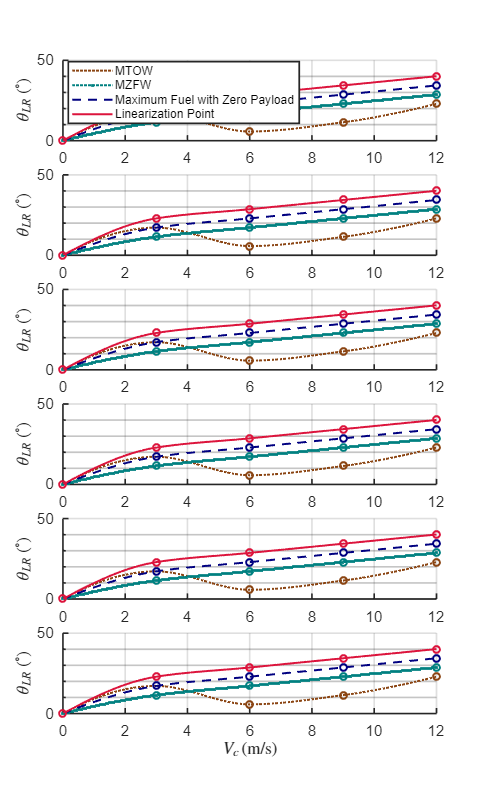

subplot(6,1,6)

% MTOW
plot(v_C_fine, theta_LR_C_1_interp .* 180 ./ pi, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5)
hold on

% MZFW
plot(v_C_fine, theta_LR_C_2_interp .* 180 ./ pi, ':.', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C_fine, theta_LR_C_3_interp .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5)
hold on

% Linearization Point
plot(v_C_fine, theta_LR_C_4_interp .* 180 ./ pi, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5)
hold on

% MTOW
plot(v_C, theta_LR_C_1 .* 180 ./ pi, 'o', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% MZFW
plot(v_C, theta_LR_C_2 .* 180 ./ pi, 'o', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Maximum Fuel with Zero Payload
plot(v_C, theta_LR_C_3 .* 180 ./ pi, 'o', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Linearization Point
plot(v_C, theta_LR_C_4 .* 180 ./ pi, 'o', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5, 'MarkerSize', 5)
hold on

% Vertical lines
plot(0, [0 max(theta_LR_C_1 .* 180 ./ pi) + 5], '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5, 'LineWidth', 5)
hold off

% Axis labels with LaTeX font
xlabel('$V_{c} \, (\mathrm{m/s})$', 'Interpreter', 'latex');
ylabel('$\theta_{LR} \; (^\circ)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([min(v_C) max(v_C)]);
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'on'; 

% Set figure size
set(gcf, 'Position', [0 0 1500 2500]);

**2.2 Hover and forward Flight**

theta_LR

theta_UR

theta_ls

theta_lc

phi

theta

delta_E

delta_R